# Seasonal Influenza: When Will it be Over?

*Authors: *Drew Pang and Emma Mascillaro

## Question

Epidemiology, or the study of disease spread, is essential in understanding the diseases all around us. This is ever more apparent today, as the results of COVID-19 models drive the public health interventions and help us plan for the future. Although not an appropriate model for COVID-19, the SIR model can be used to model many other infectious diseases, including seasonal influenza. Through abstraction, we want to take a single season of the flu and generate a simplified model. However, we must maintain some level of accuracy whereby our model accounts for enough factors to be reasonable but not too many to lose focus. Let's define the question we wish to answer:

**Question:** How long will a single season of the flu last if we account for reinfections and vaccinations? How is the length affected by the rate of vaccinations?

Why is this important? Our question is predictive and may help those looking to plan for the future. This could range from pharmacies planning flu vaccine distribution to the general public planning travel. By asking this question, we can learn how reinfections and vaccinations affect the length of an outbreak. 

## Methods:

In order to go about answering our question, we began by assessing the standard SIR model in order to determine where we would need to refine it to better fit our scenario.

**Model #1:  Standard SIR Model**

In the original SIR Model, there are three stocks (collections of people) and two flows (the rates at which people move between stocks).  These stocks and flows are listed below.

*Stocks:*                                                                                                  *Flows:*

- Suscueptible (S)                                                                          - Beta ($\beta$) -- Infection Rate

- Infected (I)                                                                                   -  Gamma ($\gamma$) -- Recovery Rate

- Recovered (R)

As depicted in the diagram of the standard SIR model, people can only move from the susceptible to infected stock and from infected to recovered stock.

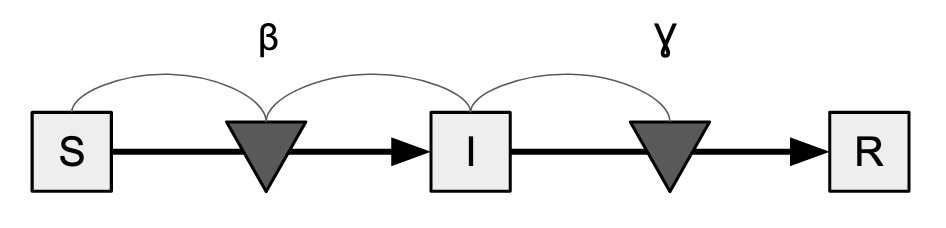

**Model #2:  Accounting for Vaccines and Reinfection**

In order to improve on the standard SIR Model, we decided to add two more flows: Mu ($\mu$) to account for the vaccination rate and Lambda ($\lambda$) to account for reinfections.  In this new system, people can flow between stocks as shown in the diagram below:

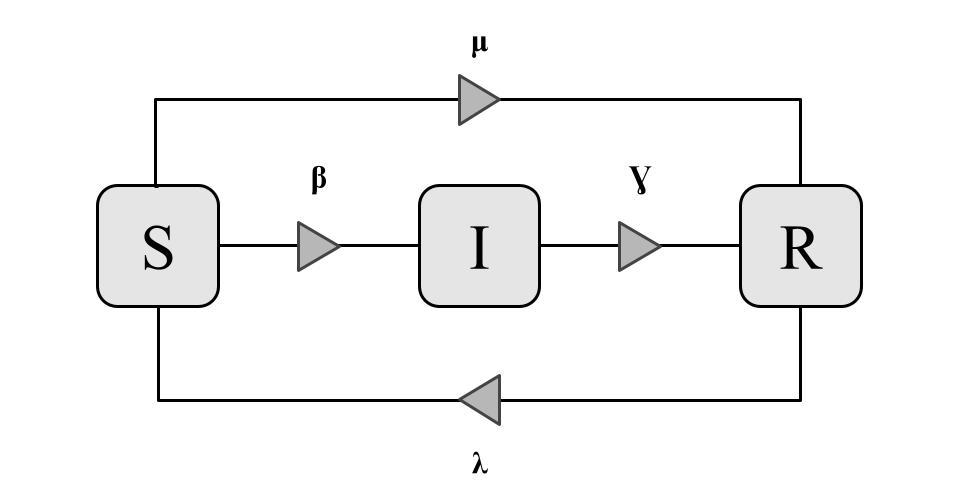

By adding in the flows for mu ($\mu$) lambda ($\lambda$), we increase the validity of our model as it better represents how diseases spread in the real world.

**Assumptions for Model #2:**

In order to implement our model to specifically study the affect of vaccination rates (when taking into account reinfections and vaccinations), we decided to make the following assumptions:

- All of our flows remain constant

- Our population does not gain or lose any people (no one is introduced into the population and no one dies)

- The disease (seasonal influenza) does not mutate

- Vaccinated people are immediately protected

- The vaccine has 100% efficacy

- The outbreak ends when the change in weekly infections drops below _____ **source

**Parameters for Model #2:**

Next, we defined the parameter values for our model.  For some parameters, we began by setting them to arbitrary values and utilized model fitting to refine them, and for other parameters, we used research to determine what their values should be.  In order to model fit, we utilized a training dataset of flu cases during the 2018-2019 season provided by the CDC **source.  Below is our list of parameters:

- Our total population is equal to the total US population **source

- Our initial stock values were derived from our training data **source

- Flows:

- $\beta$, our infection rate, was initially an arbitrary value (1/90) before it was model fit

- $\gamma$, our recovery rate, was initially set to an arbitrary value (1/2) before it was model fit

- $\mu$, our vaccination rate, was set to 465/40000 based on the statistics reported ___ **source

- $\lambda$, our reinfection rate, is set to be 17% of the infection rate as that is approximately how the flu acts, according to **source 

**Model #2 Verification:**

Once we set our assumptions and parameters, we moved on to verifying our model by ensuring that we conserved the total number of people in our population.  In order to check this, we defined all of our model fit parameters and ran our simulation function which prints sums the number of people in each stock and prints the total number of people after each week.

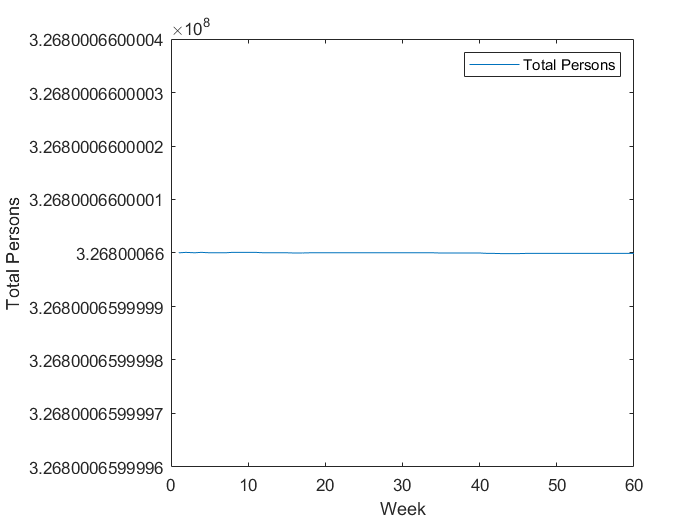

clear all
clf
% Sets the initial number of people in each stock
s_0 = 326800000; %Total population of the United States
i_0 = 66; %First data point as given by FluView from https://gis.cdc.gov/grasp/fluview/fluportaldashboard.html
r_0 = 0;

% Sets the flow values
beta = 29090/4490000000000;
gamma = 1.7;

% Sets the new flow values
mu = 465/40000; %Average flu vaccination rate per week
lambda = beta*.17; %Average reinfection rate per week

% Sets the number of weeks for the duration of the model
num_steps = 60;

[s_n, i_n, r_n, W, total_people] = sir_simulate_project_verify(s_0, i_0, r_0, beta, gamma, lambda, mu, num_steps);


% Plot
plot(total_people); label1 = "Total Persons";
xlabel("Week");
ylabel("Total Persons");
legend({label1});

**Model #2 Validation:**

If we were to go about validating our data, we would find data on flu cases over several other seasons and compare our model's prediction to their trajectories.

## Results:

#### Model Fitting

First, we will graph our model with arbitrary parameters to see what our model outputs. 

We'll take the following parameters from Worksheet 2: 

clear all
% Sets the initial number of people in each stock
s_0 = 98;
i_0 = 2;
r_0 = 0;

% Sets the flow values
beta = 1/90;
gamma = 1/2;

For $\mu
$ and $\lambda
$, we'll pick some values that seem reasonable. We'll also set the number of weeks we want our simulation to run for. 

% Sets the new flow values
mu = 1/20;
lambda = 1/270;

% Sets the number of weeks for the duration of the model
num_steps = 60;

Now, let's run our simulation and take a look at the output:

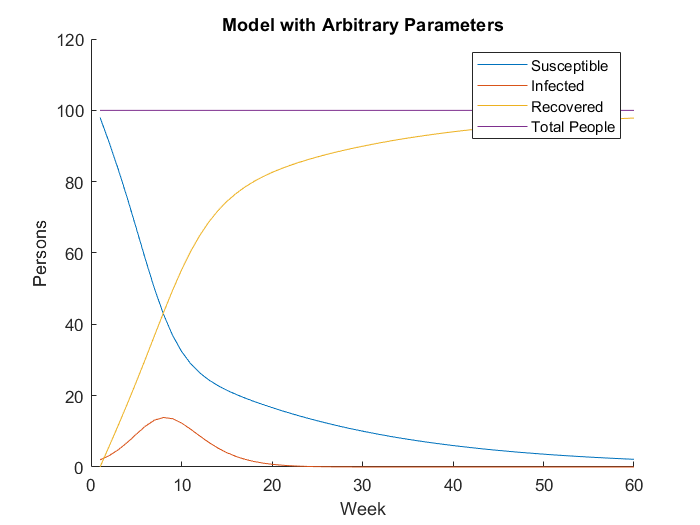

[s_n, i_n, r_n, W] = sir_simulate_project(s_0, i_0, r_0, beta, gamma, lambda, mu, num_steps);

% Plot
figure(1); clf; hold on;
plot(W, s_n); label1 = "Susceptible";
plot(W, i_n); label2 = "Infected";
plot(W, r_n); label3 = "Recovered";

plot(s_n + i_n + r_n); label4 = "Total People"; % Ensures that people are conserved

title(['Model with Arbitrary Parameters'])
xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3, label4});

We now have a model that functions as intended, but we have not yet entered our parameters based on the seasonal flu. 

Let's list the parameters we know for modeling a single season of the flu:

clear all
% Sets the initial number of people in each stock
s_0 = 326800000; %Total population of the United States
i_0 = 66; %First data point as given by FluView from https://gis.cdc.gov/grasp/fluview/fluportaldashboard.html
r_0 = 0;

% Sets the flow values.
beta = 1/90;
gamma = 1/2;

% Sets the new flow values
mu = 465/40000; %Average flu vaccination rate per week
lambda = beta*.17; %Average reinfection rate per week

% Sets the number of weeks for the duration of the model
num_steps = 60;

You may notice that beta and gamma remain unchanged. These values will be model-fitted will real data from the 2018-19 flu season. Let's graph flu data and our model with updated parameters:

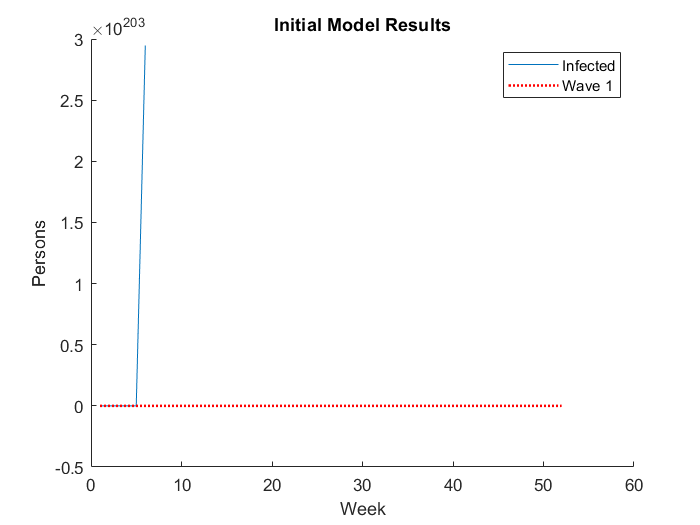

% Load the data for the 2018-19 flu season
data = readtable("data", "Delimiter", ",");

[s_n, i_n, r_n, W] = sir_simulate_project(s_0, i_0, r_0, beta, gamma, lambda, mu, num_steps);

% Plot
figure(1); clf; hold on;
plot(W, i_n); label1 = "Infected";
plot(data.W, data.I, 'r:', 'LineWidth', 1.5); label2 = "Wave 1";

title(['Initial Model Results'])
xlabel("Week")
ylabel("Persons")
legend({label1, label2})

Our model is nowhere close to the flu data. We can see that the infection rate is too high, leading our infected graph to extend so high that our wave data is not even visible. Thus, we must tweak the beta and gamma such that our model "fits" the data. 

Through model fitting, we found that our infected curve follows the data with $\beta = 725/100000000000 $ and $\gamma = 1.9$. The results are graphed below.

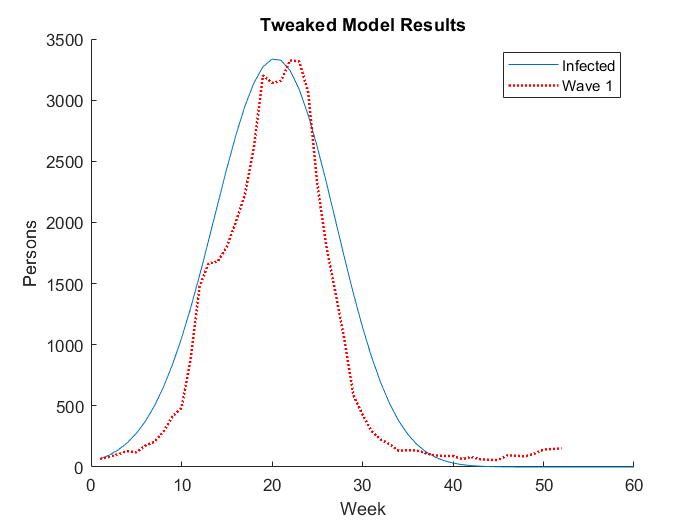

clear all
% Sets the initial number of people in each stock
s_0 = 326800000; %Total population of the United States
i_0 = 66; %First data point as given by FluView from https://gis.cdc.gov/grasp/fluview/fluportaldashboard.html
r_0 = 0;

% Sets the flow values.
beta = 725/100000000000;
gamma = 1.9;

% Sets the new flow values
mu = 465/40000; %Average flu vaccination rate per week
lambda = beta*.17; %Average reinfection rate per week

% Sets the number of weeks for the duration of the model
num_steps = 60;

% Load the data for the 2018-19 flu season
data = readtable("data", "Delimiter", ",");

[s_n, i_n, r_n, W] = sir_simulate_project(s_0, i_0, r_0, beta, gamma, lambda, mu, num_steps);

% Plot
figure(1); clf; hold on;
plot(W, i_n); label1 = "Infected";
plot(data.W, data.I, 'r:', 'LineWidth', 1.5); label2 = "Wave 1";

title(['Tweaked Model Results'])
xlabel("Week")
ylabel("Persons")
legend({label1, label2})

Our model has now successfully been model fitted. We can use this model to perform a parameter sweep on the rate of vaccinations. 

We will now parameter sweep the vaccinations rate to determine how long the flu season will last. First, we can try increasing the vaccination rate: 

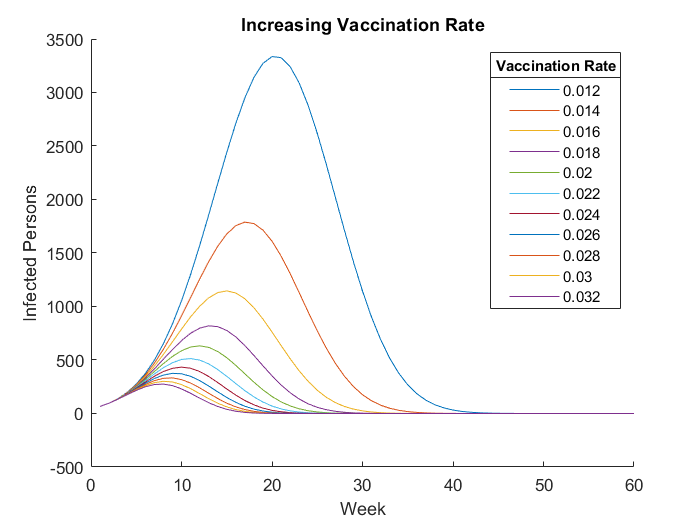

clear all
clf
hold on
% Sets the initial number of people in each stock
s_0 = 326800000;
i_0 =  66;
r_0 =  0;

% Sets the flow values
beta = 725/100000000000;
gamma = 1.9;
mu = 465/40000;
lambda = beta*.17;

% Sets the number of weeks for the duration of the model
num_steps = 60;

for mu = mu : (1/5)*mu : 3*mu

    [s_n, i_n, r_n, W] = sir_simulate_project(s_0, i_0, r_0, beta, gamma, lambda, mu, num_steps);
    
    % Plot
    figure(1);
    plot(W, i_n);
end

mu = 465/40000;

vaccination_range = [round(mu,3) : round((1/5)*mu,3) : round(3*mu,3)];
warning('off') %Ignore this :)

title(['Increasing Vaccination Rate'])
lgd = legend(string(vaccination_range));
title(lgd,'Vaccination Rate')
xlabel("Week")
ylabel("Infected Persons")
hold off

Note that the blue curve represents the average vaccination rate for the 2018-19 flu season. 

We can now graph decreasing the vaccination rate: 

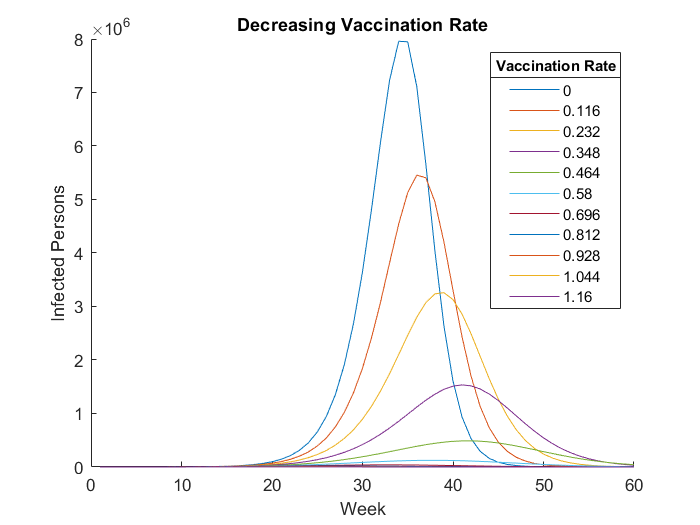

clear all
clf
hold on
% Sets the initial number of people in each stock
s_0 = 326800000;
i_0 =  66;
r_0 =  0;

% Sets the flow values
beta = 725/100000000000;
gamma = 1.9;
mu = 465/40000;
lambda = beta*.17;

% Sets the number of weeks for the duration of the model
num_steps = 60;

for mu = 0*mu : (1/10)*mu : mu

    [s_n, i_n, r_n, W] = sir_simulate_project(s_0, i_0, r_0, beta, gamma, lambda, mu, num_steps);
    
    % Plot
    figure(1);
    plot(W, i_n);
end

vaccination_range = [0*mu : round((1/10)*mu * 100,3) : round(mu * 100,3)];
warning('off') %Ignore this :)
lgd = legend(string(vaccination_range));

title(['Decreasing Vaccination Rate'])
title(lgd,'Vaccination Rate')
xlabel("Week")
ylabel("Infected Persons")
hold off

 Note that the purple curve represents the average vaccination rate for the 2018-19 flu season, though it is not clearly visible.

## Interpretation:

**Answering the Question:**

- After analyzing our results from our first model fit graph, we have found that, under normal vaccinations, we can consider the outbreak over at ___ weeks.  Additionally, after analyzing our results from our parameter sweeps of vaccination rates, we can consider the outbreak over at __ weeks for a low vaccination rate of __ and over at __ weeks for a high vaccination rate of __.

**Usefulness:**

- Ultimately, we think that the answer we got from our model is good for the purpose of displaying how effective vaccine use can be in dampening and shortening an outbreak, despite the fact that our standalone numerical values are likely innaccurate due to our assumptions and single source of training data.

**Limitations:**

**Next Steps:**

## Citations:

- CDC. (2021, May 6). *Flu Prevention: Information for Travelers*. Centers for Disease Control and Prevention. [https://www.cdc.gov/flu/school-business/travelersfacts.htm](https://www.cdc.gov/flu/school-business/travelersfacts.htm)

- *National, Regional, and State Level Outpatient Illness and Viral Surveillance*. (n.d.). Retrieved October 3, 2021, from [https://gis.cdc.gov/grasp/fluview/fluportaldashboard.html](https://gis.cdc.gov/grasp/fluview/fluportaldashboard.html)

- *Step 7: Decide an Outbreak is Over | Foodborne Outbreaks | Food Safety | CDC*. (2018, November 5). [https://www.cdc.gov/foodsafety/outbreaks/investigating-outbreaks/investigations/decision.html](https://www.cdc.gov/foodsafety/outbreaks/investigating-outbreaks/investigations/decision.html)

- *Weekly U.S. Influenza Surveillance Report | CDC*. (2021, October 1). [https://www.cdc.gov/flu/weekly/index.htm](https://www.cdc.gov/flu/weekly/index.htm)

- Sonoguchi, T., Sakoh, M., Kunita, N., Satsuta, K., Noriki, H., & Fukumi, H. (1986). Reinfection with influenza A (H2N2, H3N2, and H1N1) viruses in soldiers and students in Japan. The Journal of Infectious Diseases, 153(1), 33–40. [https://doi.org/10.1093/infdis/153.1.33](https://doi.org/10.1093/infdis/153.1.33)